**1. Color balance , Saturation,and Demosaicing **

**(1)White balance**

Apply the white balance on "sky.jpg" and name the output image as "WhiteBalanceImage".


$$I(x,y)=0.299f_R(x,y)+0.587f_G(x,y)+0.114 f_B(x,y)\\
k_R=\frac{\overline I}{\overline{f_R}},k_G=\frac{\overline I}{\overline{f_G}},k_B=\frac{\overline I}{\overline{f_B}}\\$$


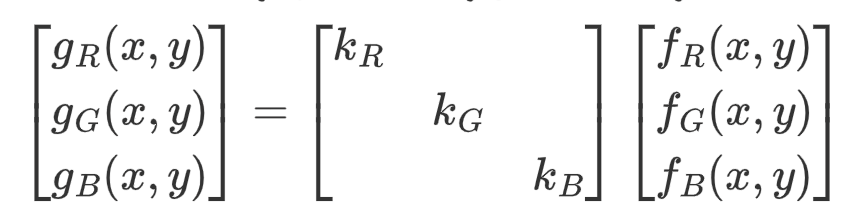

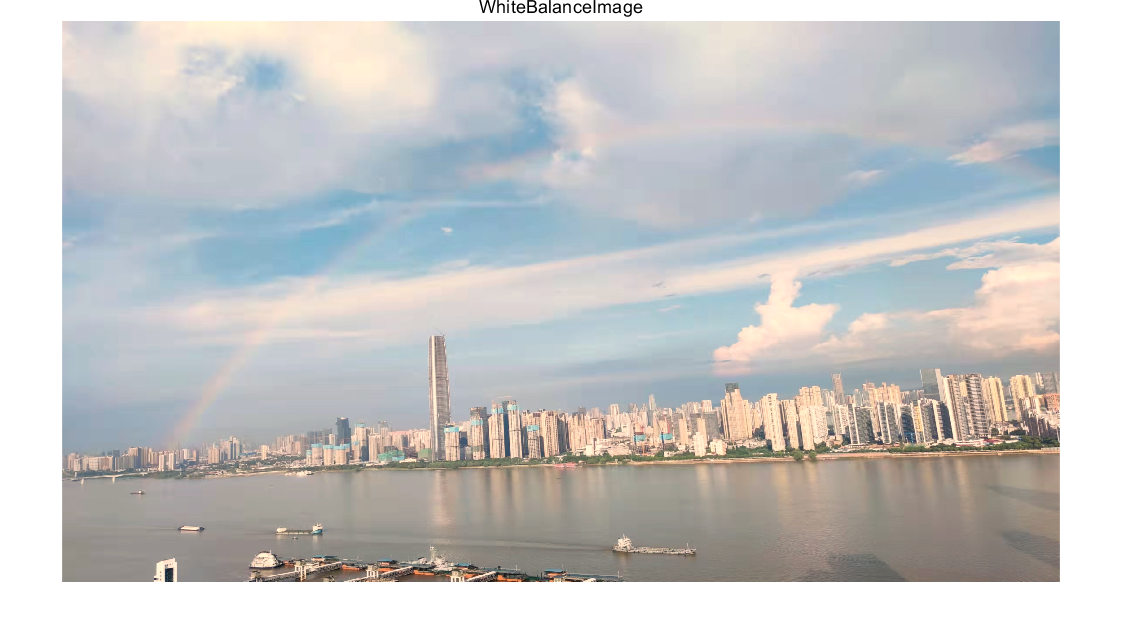

clear

RGB = imread("sky.jpg");
RGB = im2double(RGB);

R = RGB( : ,  : , 1);
G = RGB( : ,  : , 2);
B = RGB( : ,  : , 3);

I = 0.299*R + 0.587*G + 0.114*B;

kr = mean(I(:)) / mean(R(:));
kg = mean(I(:)) / mean(G(:));
kb = mean(I(:)) / mean(B(:));

newimg = cat(3, kr*R, kg*G, kb*B);

subplot(1,1,1);
imshow(newimg), title("WhiteBalanceImage");

**(2)Adjust Saturation**

Increase the saturation of  "sky.jpg" by 50% ,and name the output image as "SaturationImage".

**Also,You cannot use  the function“rgb2hsv()or hsv2rgb()”**

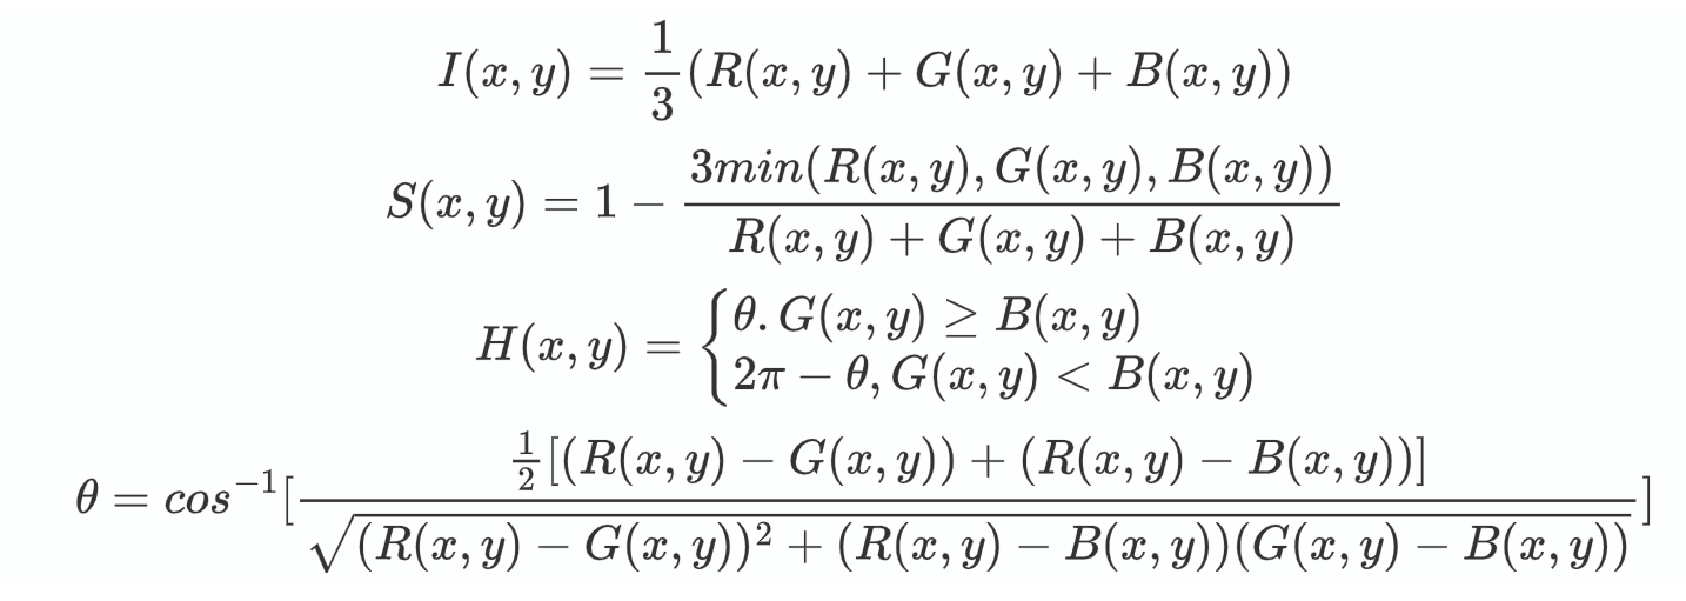

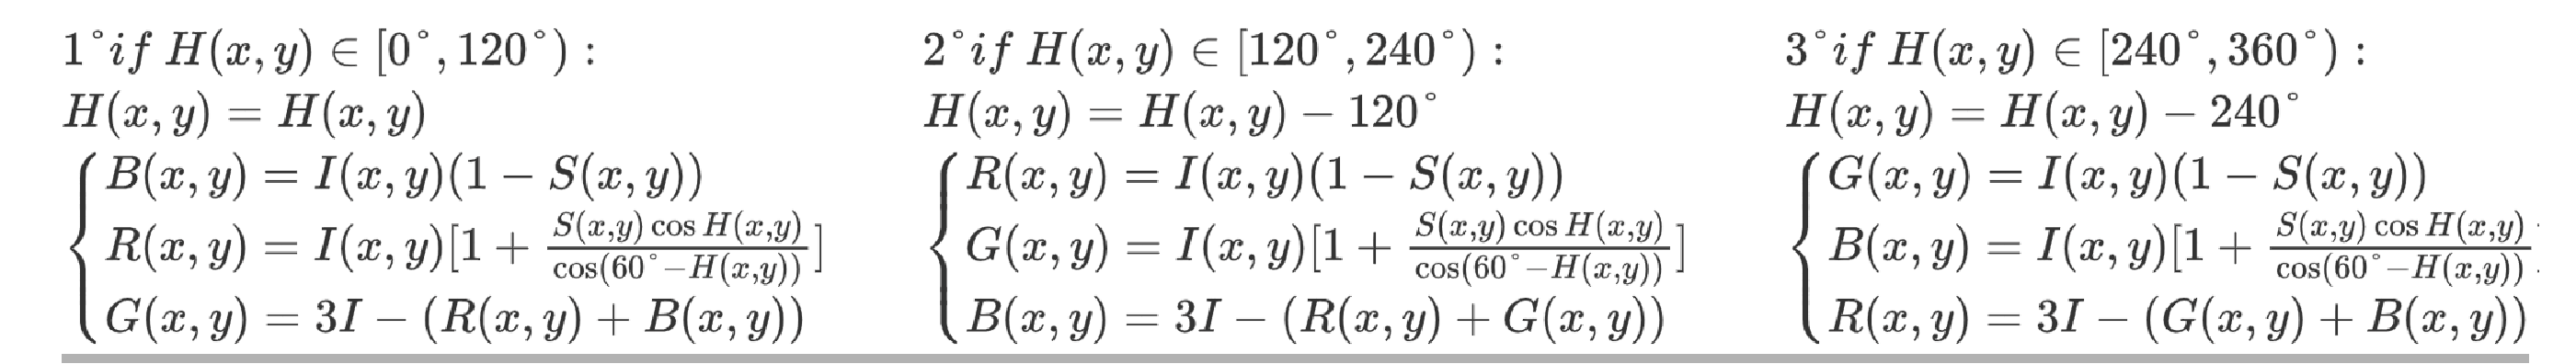

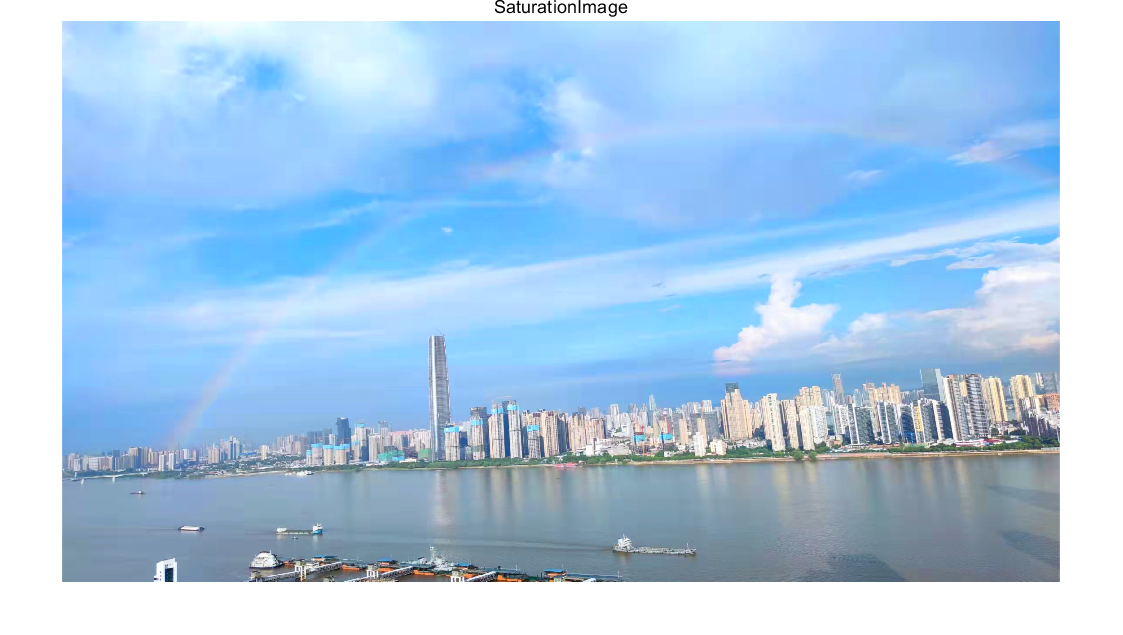

clear

RGB = imread("sky.jpg");
RGB = im2double(RGB);

R = RGB( : ,  : , 1);
G = RGB( : ,  : , 2);
B = RGB( : ,  : , 3);


I = (R + G + B)/3;


m = R;
m = min(m, G);
m = min(m, B);


S = 1 - 3*m ./ (R + G + B);

S = 1.5*S;

theta = acosd( (2*R - G - B) ./ ( 2 * sqrt( (R - G).^2 + (R - B).*(G - B) ) ) );

H_m = theta;

a = (G >= B );
b = (G < B);

H_m(a) = theta(a);   
H_m(b) = 360 - theta(b);


x = (H_m >= 0 & H_m < 120);
    
    B(x) = I(x) .* (1 - S(x));
    R(x) = I(x) .* ( 1 + S(x).*cosd(H_m(x))./cosd(60 - H_m(x)) );
    G(x) = 3*I(x) - (R(x) + B(x));


y = (H_m >= 120 & H_m < 240 );

    H_m(y) = H_m(y) - 120;

    R(y) = I(y) .* (1 - S(y));
    G(y) = I(y) .* ( 1 + S(y).*cosd(H_m(y))./cosd(60 - H_m(y)) );
    B(y) = 3*I(y) - (R(y) + G(y));


z = (H_m >= 240 & H_m < 360 );

    H_m(z) = H_m(z) - 240;
    
    G(z) = I(z) .* (1 - S(z));
    B(z) = I(z) .* ( 1 + S(z).*cosd(H_m(z))./cosd(60 - H_m(z)) );
    R(z) = 3*I(z) - (G(z) + B(z));


newimg = cat(3, abs(R), abs(G), abs(B));

subplot(1,1,1);
imshow(newimg), title("SaturationImage");

**(3)Demosaicing**

The initial image is given as "flower.mat". Please use the demosaicing algorithm to convert this single-channel image to a three-channel RGB image. Name the output image as "RGBImage". **You cannot use the function“demosaic()”**

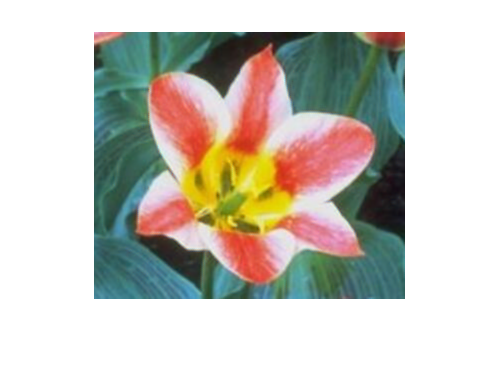

clear

raw = struct2array(load("flower.mat"));
[h, w, c]=size(raw);


% BP = BayerPadding
% h = height, w = width, c = channel
BP = zeros(h + 2, w + 2);
BP(2:h + 1, 2:w + 1) = raw;
BP(1, :) = BP(3, :);
BP(h + 2, :) = BP(h, :);
BP(:, 1) = BP(:, 3);
BP(:, w + 2) = BP(:, w);
imDst = zeros(h + 2, w + 2, c);


for ver = 2:h + 1

    for hor = 2:w + 1

        if(1 == mod(ver - 1, 2))

            if(1 == mod(hor - 1, 2))

                imDst(ver, hor, 3) = BP(ver, hor);
                imDst(ver, hor, 1) = (BP(ver - 1, hor - 1) + BP(ver - 1, hor + 1) ...
                                     + BP(ver + 1, hor - 1) + BP(ver + 1, hor + 1)) / 4;
                imDst(ver, hor, 2) = (BP(ver - 1, hor) + BP(ver, hor - 1) ...
                                     + BP(ver, hor + 1) + BP(ver + 1, hor)) / 4;

            else

                imDst(ver, hor, 2) = BP(ver, hor);
                imDst(ver, hor, 1) = (BP(ver - 1, hor) + BP(ver + 1, hor)) / 2;
                imDst(ver, hor, 3) = (BP(ver, hor - 1) + BP(ver, hor + 1)) / 2;

            end
        else

            if(1 == mod(hor - 1, 2))

                imDst(ver, hor, 2) = BP(ver, hor);
                imDst(ver, hor, 1) = (BP(ver, hor - 1) + BP(ver, hor + 1)) / 2;
                imDst(ver, hor, 3) = (BP(ver - 1, hor) + BP(ver + 1, hor)) / 2;

            else

                imDst(ver, hor, 1) = BP(ver, hor);
                imDst(ver, hor, 2) = (BP(ver - 1, hor) + BP(ver, hor - 1) ...
                                     + BP(ver, hor + 1) + BP(ver + 1, hor)) / 4;
                imDst(ver, hor, 3) = (BP(ver - 1, hor - 1) + BP(ver - 1, hor + 1) ...
                                     + BP(ver + 1, hor - 1) + BP(ver + 1, hor + 1)) / 4;

            end

        end

    end

end
 

imDst = uint8(imDst(2:h + 1, 2:w + 1, :));
figure, imshow(imDst);

## 2. Noise generation and degeneration

(1) ***Noise generation***

Add the following noise to the initial image separately：

Gaussian noise：mean and variance are 25 and 25 respectively;

Salt-and-pepper noise：intensities are 0 and 255 with probabilities $P_{salt} = P_{pepper} = 0.05$;

Name the output images as "NoiseImage1", "NoiseImage2" and display both images. **You are free to use the function "imnoise" or other built-in functions to generate the noise.**

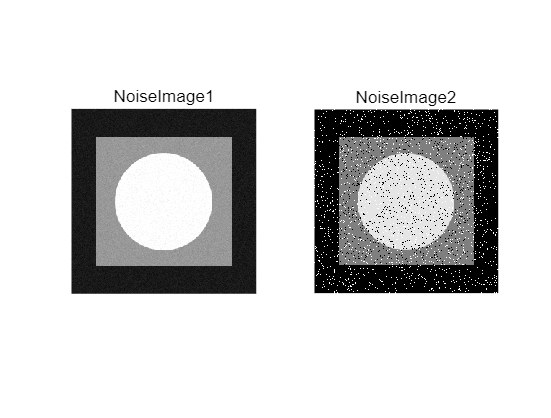

clear

x = im2double(struct2array(load("init_img.mat")));

NoiseImage1 = imnoise(x, "gaussian", 25 / 255, 25 / 255^2);
subplot(1, 2, 1);
imshow(NoiseImage1), title("NoiseImage1");

NoiseImage2 = imnoise(x, "salt & pepper", 0.1);
subplot(1, 2, 2);
imshow(NoiseImage2), title("NoiseImage2");

**(2) *****Noise degeneration***

Please design a median filter and an average filter, and apply both your filters to the "NoiseImage1" and"NoiseImage2". Then display all your output image results.

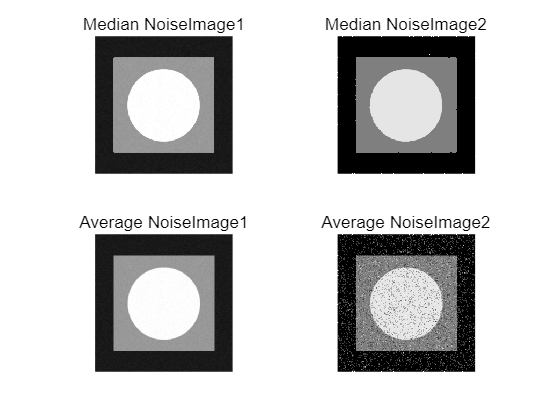

median_NoiseImage1 = median_filter(NoiseImage1, 3);
median_NoiseImage2 = median_filter(NoiseImage2, 3);

average_NoiseImage1 = average_filter(NoiseImage1, 2);
average_NoiseImage2 = average_filter(NoiseImage2, 2);
% the source code of two functions are in the end of this PDF("My functions")


subplot(1, 1, 1);
subplot(2, 2, 1);
imshow(median_NoiseImage1), title("Median NoiseImage1");

subplot(2, 2, 2);
imshow(median_NoiseImage2), title("Median NoiseImage2");

subplot(2, 2, 3);
imshow(average_NoiseImage1), title("Average NoiseImage1");

subplot(2, 2, 4);
imshow(average_NoiseImage2), title("Average NoiseImage2");

## 3. **Log/gamma Transformation and histogram equalization and matching**

**(1)*****Histogram***

Develop a function which computes the **gray-level histogram** of the "origin.png". Then using this function to find the histogram and display it.**You cannot use the function “imhist()or histogram() ”**

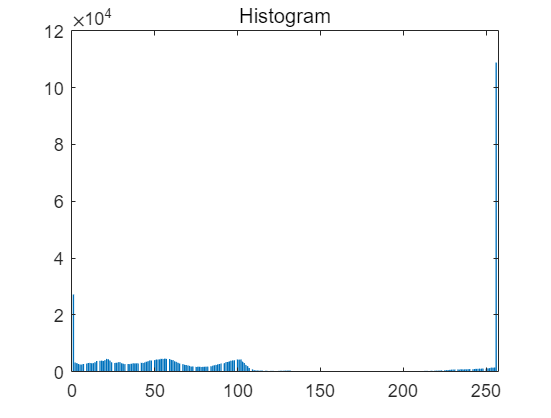

clear

img = imread("origin.png");

histogram = gray_level_histogram(img);
% the source code of gray_level_histogram() is in the end of this PDF("My functions")

subplot(1, 1, 1)
bar(histogram), title('Histogram');

**(2)Log Transformation and Gamma Transformation**

use transform function $s=c\log(1+r)$  and $s=c\cdot r^\gamma$  $$(\gamma=0.4)$$to deal with the image.Display the output image and its gray-level histogram.

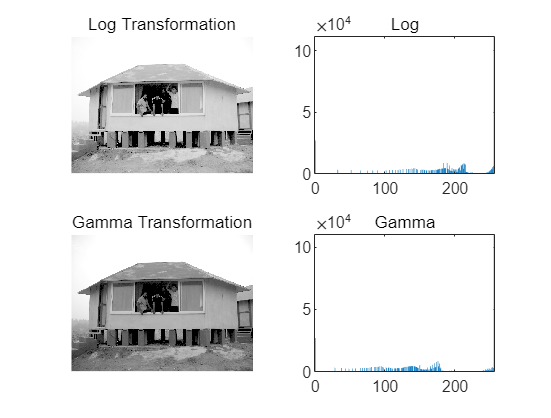

clear

Img = imread("origin.png");


Gray_log = mat2gray(log(1 + double(Img)));
Histogram_log = gray_level_histogram(im2uint8(Gray_log));

Gray_gamma = mat2gray(double(Img).^0.4);
Histogram_gamma = gray_level_histogram(im2uint8(Gray_gamma));
% the source code of gray_level_histogram() is in the end of this PDF("My functions")


subplot(2, 2, 1);
imshow(Gray_log), title("Log Transformation");

subplot(2, 2, 2);
bar(Histogram_log), title("Log");

subplot(2, 2, 3);
imshow(Gray_gamma), title("Gamma Transformation");

subplot(2, 2, 4);
bar(Histogram_gamma), title("Gamma");

**(3)*****Histogram equalization***

**Use the function histeq()** to apply histogram equalization on the "Lena.png". Display the output image and its gray-level histogram. 

If you can design a function by youself instead of using function histeq() in this part, you can get a Bonus scores(5’)

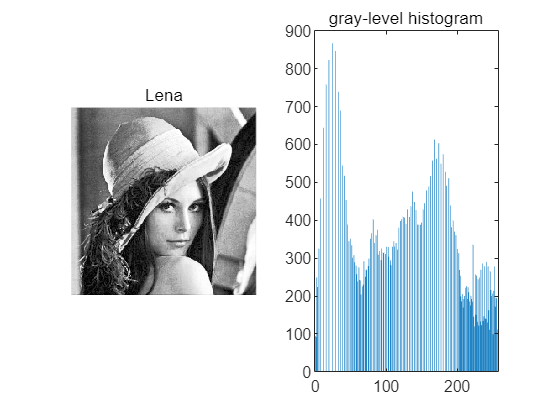

clear

img_lena = imread("Lena.png");


img_lena = hist_equalization(img_lena);   
% the source code of histEqualization() is in the end of this PDF("My functions")
hist_lena = gray_level_histogram(img_lena);


subplot(1, 1, 1);
subplot(1, 2, 1);
imshow(img_lena), title("Lena");

subplot(1, 2, 2);
bar(hist_lena), title("gray-level histogram")

**(4)*****Histogram matching***

**Use the function histeq()**  to apply the histogram matching between the source image and the target image. Use this function to display the output image. And you also need to display the gray-level histogram of the source image, the target image and the output image.

If you can design a function by youself instead of using function histeq() in this part, you can get a Bouns scores(5’)

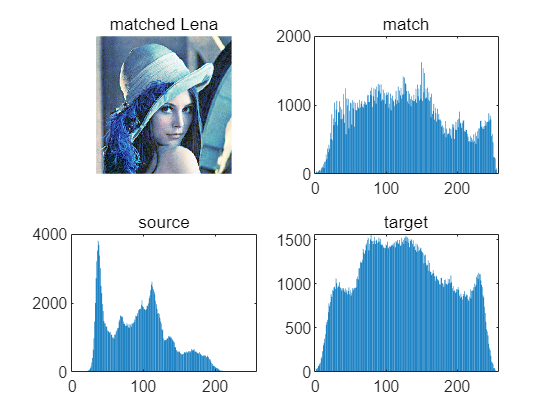

clear

s = imread("source.jpg");
t = imread("target.jpg");


m = [];
for i = 1:size(s, 3)

    med = histogram_matching(s(:,:,i), t(:,:,i));
    % the source code of histogram_matching() is in the end of this PDF("My functions")
    m = cat(3, m, med);

end


H_m = gray_level_histogram(m);
H_s = gray_level_histogram(s);
H_t = gray_level_histogram(t);


subplot(1, 1, 1);
subplot(2, 2, 1);
imshow(m), title("matched Lena");

subplot(2, 2, 2);
bar(H_m), title("match");

subplot(2, 2, 3);
bar(H_s), title("source");

subplot(2, 2, 4);
bar(H_t), title("target");

# **My functions：**

**1) median_filter & average_filter**

function output = median_filter(NoiseImage, window_size)


    output = NoiseImage;
    
    [pix_h, pix_w] = size(NoiseImage);
    
    win_w = window_size;
    win_h = window_size;
    
    edge_x = floor(win_w / 2);
    edge_y = floor(win_h / 2);
    
    for x = (edge_x + 1 : pix_w - edge_x)
    
        for y = (edge_y + 1: pix_h - edge_y)
    
            i = 1;
    
            for fx = 1 : win_w
    
                for fy = 1 : win_h
    
                    win(i) = NoiseImage( (x + fx - edge_x - 1), (y + fy - edge_y - 1) );
    
                    i = i + 1;
                
                end
            
            end
    
            output(x, y) = median(win);
        
        end
    
    end


end




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




function output = average_filter(NoiseImage, window_size) 


    output = NoiseImage;
    
    [pix_h, pix_w] = size(NoiseImage);
    
    win_w = window_size;
    win_h = window_size;
    
    edge_x = floor(win_w / 2);
    edge_y = floor(win_h / 2);
    
    for x = (edge_x + 1 : pix_w - edge_x)
    
        for y = (edge_y + 1: pix_h - edge_y)
    
            i = 1;
    
            for fx = 1 : win_w
    
                for fy = 1 : win_h
    
                    win(i) = NoiseImage( (x + fx - edge_x - 1), (y + fy - edge_y - 1) );
    
                    i = i + 1;
                
                end
            
            end
    
            output(x, y) = mean(win);
        
        end
    
    end


end

**2)gray_level_histogram**

function histogram = gray_level_histogram(image)


    if(size(image, 3)>1)

        image = rgb2gray(image);

    end
    

    counts = zeros(256, 1);

    for i = 0:255

        counts(i + 1) = sum(sum(image == i));

    end
    
          
    histogram = counts;

end    

**3)histogram_equalization**

function [output, cdf] = hist_equalization(img)


    L = 256;

    if(size(img, 3)>1)

        img = rgb2gray(img);

    end
    

    counts = zeros(256, 1);

    for i = 0:255

        counts(i + 1) = sum(sum(img == i));

    end
    
    
    p = counts / (size(img, 1) * size(img, 2));    
    cdf = round((L - 1) * cumsum(p));
    
    
    output = uint8(zeros(size(img)));

    for k = 1:size(cdf, 1)
    
        output(img == k - 1) = cdf(k);
    
    end

end

**4)histogram_matching**

function output = histogram_matching(source, target)

    M = zeros(256, 1,"uint8");                         
    % Store mapping

    [~,cdf1] = hist_equalization(source);
    [~,cdf2] = hist_equalization(target);
    

    for idx = 1 : 256
        [~, ind] = min(abs(cdf1(idx) - cdf2));
        M(idx) = ind - 1;
    end
    
    
    output = M(double(source) + 1);


end